load dataset-5a

tableQ1A = readtable("Q1A.xlsx");
H1 = rmmissing(tableQ1A.Height_S1);
Q1 = rmmissing(tableQ1A.Discharge_S1);
Q2 = rmmissing(tableQ1A.Discharge_S2);
Q3 = rmmissing(tableQ1A.Discharge_S3);

tableQH_S1 = readtable("QH_S1.xlsx");
HS1 = tableQH_S1.H_S1;
QS1 = tableQH_S1.Q_S1;

tableQH_S3 = readtable("QH_S3.xlsx");
HS3 = tableQH_S3.H_S3;
QS3 = tableQH_S3.Q_S3;

รับค่า H D56-D60 ที่สถานี S1 จาก server

dataWater = webread("http://192.168.1.125/water");
tWater = struct2table(dataWater.data );
H1 = [H1(1:55);tWater.w_height(tWater.date==56);tWater.w_height(tWater.date==57);tWater.w_height(tWater.date==58);tWater.w_height(tWater.date==59);tWater.w_height(tWater.date==60)];
%H1 = [H1;[115.99 115.96 115.93 115.90 115.89]']; %เผื่อไม่มีค่ามาจาก server 

แสดงค่า H ที่สถานี S1

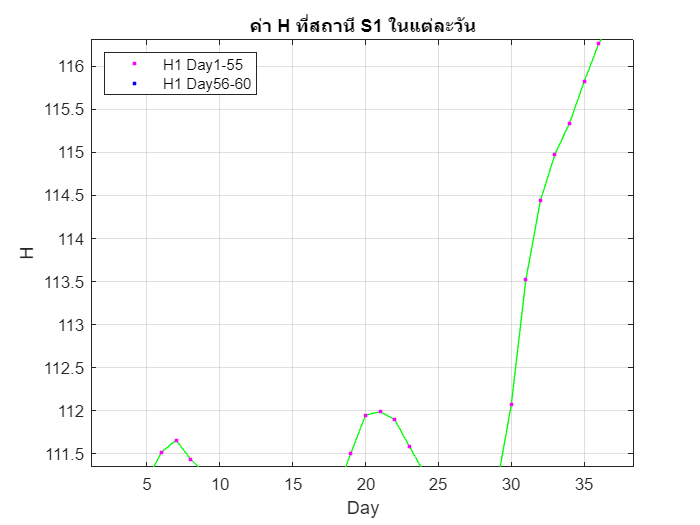

plot(1:60,H1,'g')
hold on
plot(1:55,H1(1:55),'m.')
plot(56:60,H1(56:60),'b.')
hold off
grid on
xlabel('Day');
ylabel('H');
title('ค่า H ที่สถานี S1 ในแต่ละวัน');
legend({'','H1 Day1-55','H1 Day56-60'},'Location','northwest');

fprintf('Day56: %.2f\nDay57: %.2f\nDay58: %.2f\nDay59: %.2f\nDay60: %.2f', H1(56),H1(57),H1(58),H1(59),H1(60));

Day56: 115.99
Day57: 115.96
Day58: 115.93
Day59: 115.90
Day60: 115.89